clc;
close all;
clear;
load("robot.mat");

to_1 = [242, -101, 110;  242, -101, 81; 242, -101, 110;  221, 70, 110;  221, 70, 81;                221, 70, 110];
to_2 = [242, -69, 110;   242, -69, 81;  242, -69, 110;   220, 107, 110; 220, 107, 81;               220, 107, 110];
to_3 = [204, -100, 110;  204, -100, 81; 204, -100, 110;  186, 105,110;  186, 105, 81;               186, 105, 110];
to_4 = [167, -72, 110;   167, -72, 81;  167, -72, 110;   166, 88, 110;  166, 88, 81;                166, 88,110];
to_5 = [166, -106, 110;  166, -106, 81; 166, -106, 110;  186, 64, 110;  186, 64, 81;  186, 70, 81;  186, 70,110];
to_6 = [203, -67, 110;    203, -67, 81; 203, -67, 110;   241.5, 95, 110;241.5, 95, 81;241.5, 90, 81;241.5, 90,110];

back_1 = [241.5, 91, 110; 241.5, 91, 81;241.5, 91, 110;   203, -67 110;   203, -67, 81;  203, -67, 110];
back_2 = [186, 70, 110;   186, 70, 81;  186, 70, 110;   166, -106, 110; 166, -106, 81; 166, -106, 110];
back_3 = [221, 70, 110;   221, 70, 81;  221, 70, 110;   242, -101, 110; 242, -101, 81; 242, -101, 110];
back_4 = [220, 107, 110;  220, 107, 81; 220, 107, 110;  242, -69, 110;  242, -69, 81;  242, -69, 110];
back_5 = [186, 105, 110;  186, 105, 81; 186, 105,  110; 204, -100, 110; 204, -100, 81;204, -100, 110];
back_6 = [166, 88,110;    166, 88, 81;  166, 88, 110;   167, -72, 110;  167, -72, 81;  167, -72, 110];
%calculate joint angle
target_points = cat(1,to_1,to_2,to_3,to_4,to_5,to_6,back_1,back_2,back_3,back_4,back_5,back_6);
target_points = target_points / 1000;
constraint_theta = [-100, 160; %Angle constraints
                    -40-90, 70-90;
                    -170, 60;
                    -350, 350; 
                    -205+90, 36+90;
                    -360, 360];
constraint_theta = constraint_theta/180*pi;

ik = inverseKinematics('RigidBodyTree', robot);
weights = [0.01 0.01 0.01 0.1 0.1 0.1]; 
endEffectorName = 'arm6';
for i = 1:6
    robot.Bodies{i}.Joint.PositionLimits = constraint_theta(i,:);
end
% ik
calculated_theta_list = zeros(size(target_points, 1), length(robot.homeConfiguration));
for i = 1:size(target_points, 1)
    targetPosition = target_points(i, :);
    targetPose = trvec2tform(targetPosition); 
    [solution, solnInfo] = ik(endEffectorName, targetPose, weights, robot.homeConfiguration);
    if solnInfo.ExitFlag > 0
        calculated_theta_list(i, :) = rad2deg(solution); 
    else
        disp(['IK solution not found for position ', num2str(i)]);
    end
end

disp('Calculated joint angles using Inverse Kinematics:');

Calculated joint angles using Inverse Kinematics:



% correct the format
calculated_theta_list = calculated_theta_list';
disp(calculated_theta_list); %show

  Columns 1 through 18

  -22.6535  -22.6535  -22.6535   17.5752   17.5752   17.5752  -15.9141  -15.9141  -15.9141   25.9366   25.9366   25.9366  -26.1139  -26.1139  -26.1139   29.4454   29.4454   29.4454
  -43.7335  -36.1580  -43.7335  -58.5053  -49.8748  -58.5053  -49.1223  -41.2224  -49.1223  -52.5165  -44.3774  -52.5165  -60.6221  -51.7958  -60.6221  -66.7801  -57.3143  -66.7801
  -16.0115  -16.7246  -16.0115    5.3754    4.7194    5.3754   -8.0121   -8.6914   -8.0121   -3.0839   -3.7501   -3.0839    8.2864    7.6306    8.2864   16.4950   15.8305   16.4950
    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000
   59.7450   52.8826   59.7450   53.1300   45.1554   53.1300   57.1344   49.9138   57.1344   55.6004   48.1275   55.6004   52.3357   44.1652   52.3357   50.2851   41.4838   50.2851
   22.6535   22.6535   22.6535  -17.5752  -17.5752  -17.5752   15.9141 

calculated_theta_list = calculated_theta_list*pi/180; % use rad in matlab
calculated_theta_list(6,:) = 0; % keep zero
num_joint_angle = size(calculated_theta_list,2); % joint angle nums

Step = 30;
tip_positions = zeros([Step*num_joint_angle,3]);
total_steps = Step * num_joint_angle;
num_joints = 6;

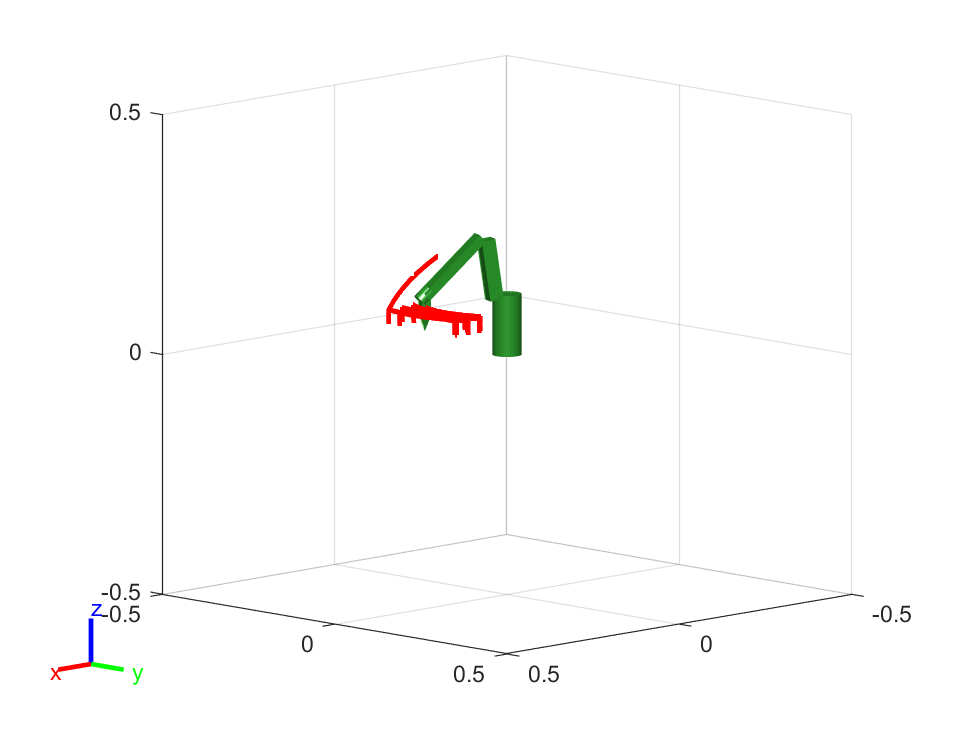

fig = figure('Color', [1 1 1]);
ax = axes('Parent', fig, 'DataAspectRatio', [1 1 1], 'XLim', [-0.5 0.5], 'YLim', [-0.5 0.5], 'ZLim', [-0.5 0.5]);
set(ax, 'XDir','reverse', 'YDir','reverse', 'ZDir','normal');
lighting gouraud;
light('Position',[1 1 1],'Style','infinite');
material dull;  
view(3);
view(ax, -45, 10);
grid on;
hold(ax, 'on');
zoom on;
pan on;
robotPlot = show(robot, calculated_theta_list(:,1), 'Parent', ax, 'PreservePlot', false);
trajectoryPlot = plot3(ax, NaN, NaN, NaN, 'r', 'LineWidth', 2); %trajectoryPlot

v = VideoWriter('Task5.avi');
v.FrameRate = 15;
open(v);
homeconfig = robot.homeConfiguration;
calculated_theta_list = [homeconfig, calculated_theta_list];
for j = 2:size(calculated_theta_list, 2)
    Qd = calculated_theta_list(:, j) - calculated_theta_list(:, j - 1);
    idx = (j - 2) * Step;
    for i = 1:Step
        q = calculated_theta_list(:, j - 1) + Qd / Step * i;
        tip_positions(i + idx, :) = cal_tip_positions(q);
        show(robot, q, 'Parent', ax, 'PreservePlot', false, "Collisions", "on", "Frames", "off");
        set(trajectoryPlot, 'XData', tip_positions(1:i + idx, 1), 'YData', tip_positions(1:i + idx, 2), 'ZData', tip_positions(1:i + idx, 3));
        drawnow;

        frame = getframe(gcf);
        writeVideo(v, frame);
    end
end
hold(ax, 'off');

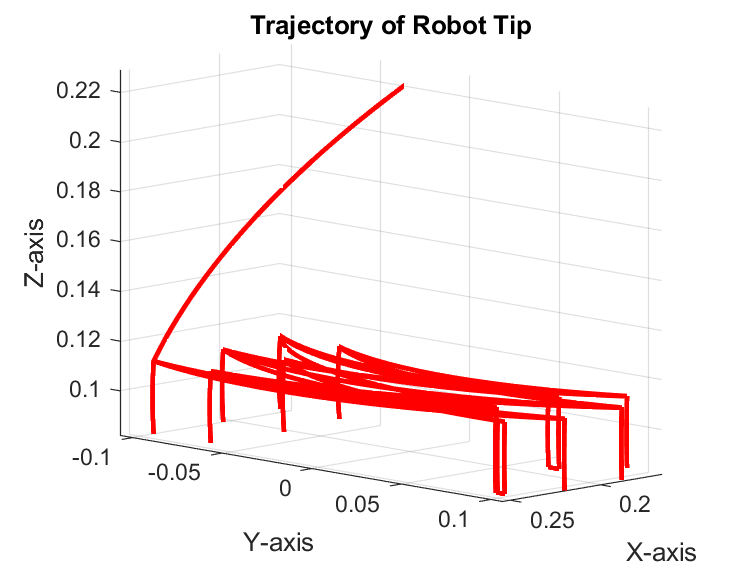

close(v);
figure('Color', [1 1 1]);
plot3(tip_positions(:, 1), tip_positions(:, 2), tip_positions(:, 3), 'r', 'LineWidth', 2);
grid on;
xlabel('X-axis');
ylabel('Y-axis');
zlabel('Z-axis');
title('Trajectory of Robot Tip');
axis equal;
view(135, 10); 

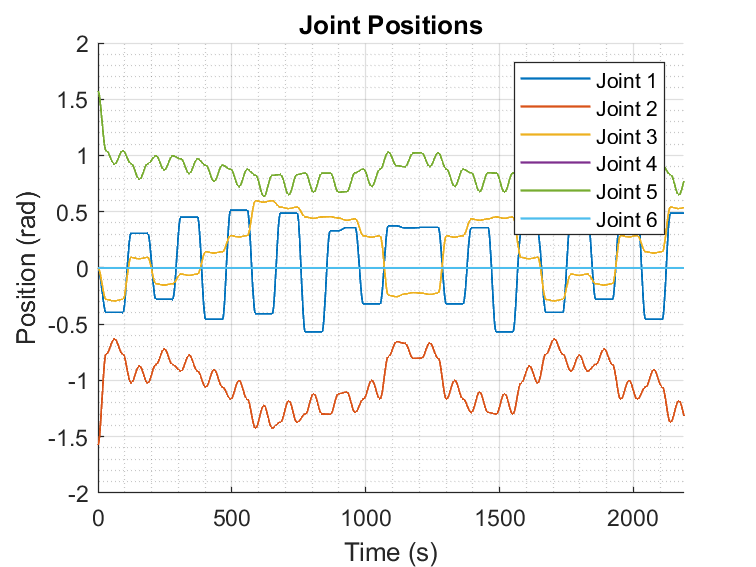

joint_positions = [];
joint_velocities = [];
%calculate joint positions and velocities
for i = 1:num_joints
    for j = 2:num_joint_angle 
        [pos, vel] = calculateJointMotion(calculated_theta_list(:,j-1), calculated_theta_list(:,j), Step);
        joint_positions = [joint_positions, pos];
        joint_velocities = [joint_velocities, vel];
    end  
end
%plot joint_positions
t = 0:(size(joint_positions, 2) - 1);
figure('Color', [1 1 1]);
hold on;
grid on;
grid minor;
for i = 1:num_joints
    plot(t, joint_positions(i,:), 'LineWidth', 1, 'DisplayName', ['Joint ' num2str(i)]);
end
xlim([0, (num_joint_angle-1)*Step - 1]);
title("Joint Positions");
xlabel("Time (s)");
ylabel("Position (rad)");
legend;

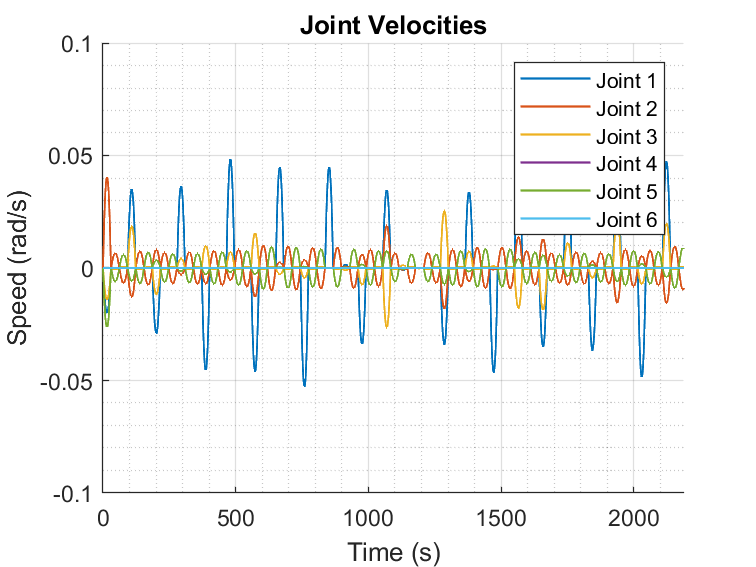

%plot joint_velocities
figure('Color', [1 1 1]);
hold on;
grid on;
grid minor;
for i = 1:num_joints
    plot(t, joint_velocities(i,:), 'LineWidth', 1, 'DisplayName', ['Joint ' num2str(i)]);
end
xlim([0, (num_joint_angle-1)*Step - 1]);
ylim([-0.1,0.1]);
title("Joint Velocities");
xlabel("Time (s)");
ylabel("Speed (rad/s)");
legend;